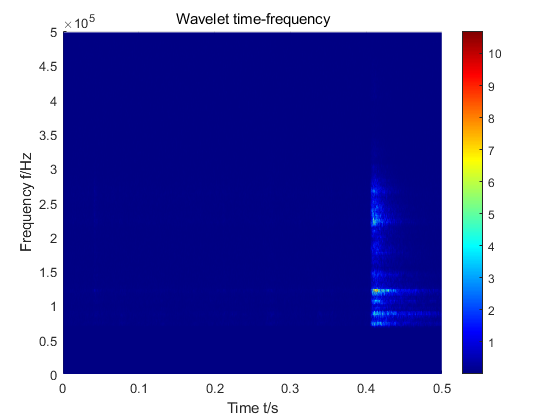

clear all;
%[s,fs]=audioread('combined.wav');

tmp = readtable('79.csv');
s = table2array(tmp(:,2)); %Load 1st audio file
%x = 10 * log10((x).^2);
fs= 1000000;
t1 = fs * 0.49;
t2 = fs * 0.99;
s = fir_hpf(s,fs,30,22500,23000);
s = s(t1:t2);

FS=length(s); % Length of x;

h = hanning(500);  % 63个节点的汉宁窗
[tfr,f, t] = stft(s,fs, 'window', h);  % 参数一个都不能少 
surf(t, abs(f(1:length(f)/2)), abs(tfr(1:length(f)/2,:)));
colormap('jet');
%view(2);
xlabel('Time t/s');
ylabel('Frequency f/Hz');
title('Wavelet time-frequency');
view(2);
colorbar;
shading flat;

% caxis([0 1.2]);

% t=(0:FS-1)*2/fs;
% wavename='dmey';
% totalscal=256; % The total amount of scales
% wcf=centfrq(wavename); % Central frequency
% cparam=2*wcf*totalscal; % Parament to obtain proper scale
% a=totalscal:-1:1;  
% scal=cparam./a; 
% coefs=cwt(s,scal,wavename); % coefficiency of wavelet
% coefs = abs(coefs);
% f=scal2frq(scal,wavename,1/fs); % turn scales to frequecies
% figure(1)
% surf(t,f,coefs); % draw 3-D frequency-time figures
% view(2);
% grid off;
% shading interp;
% colormap(jet);
% colorbar('Ticks',[0,0.02,0.04,0.06,0.08,0.1,0.12]);
% xlabel('Time t/s');
% ylabel('Frequency f/Hz');
% title('Wavelet time-frequency');


% figure(2)
% plot(s);
% title('Original Signal s');
% 
% nodes=[7;8;9;10;11;12;13;14];   % nodes for 3rd level
% ord=wpfrqord(nodes);  % resort the nodes
% nodes_ord=nodes(ord); % new nodes after resorting
% wpt=wpdec(s,3,'dmey'); % Decompose：meyr level 3
% rex3(:,4)=wprcoef(wpt,nodes_ord(4));  % reconstruction, coeffs after resorting 72-96Hz
%  
% figure(3)                       % draw 3rd node after reconstruction
% x_sign=rex3(:,4); 
% N=length(x_sign);                % sampling points
% signalFFT=abs(fft(x_sign,N));    % Amplitude
% Y=2*signalFFT/N;
% f=(0:N/2)*(fs/N);
% plot(f,Y(1:N/2+1));
% ylabel('amp'); 
% xlabel('frequency');
% xticks([0 50000 72000 80000 96000 100000 150000 200000]);
% xticklabels({'0','50','72','80','96','100','150','200'});
% title(['Level 3 Subband frequency spectrum 72~96 kHz']);
% grid on;


% function [y] = fir_bpf(x,fs)
% %设计一个高通滤波器,要求把400Hz的频率分量保留,其他分量滤掉
% wp = 44000/(fs/2);  %通带截止频率
% ws = 45000/(fs/2);  %阻带截止频率
% alpha_p = 5; %通带允许最大衰减为  db
% alpha_s = 10;%阻带允许最小衰减为  db
% %获取阶数和截止频率
% [N, wc] = buttord( wp , ws , alpha_p , alpha_s);
% %获得转移函数系数
% [b, a] = butter(N,wc,'high'); 
% %滤波
% y = filter(b,a,x);
% end


function [y]=fir_hpf(x,Fs,As,fp,fs)
%该函数采用kaiser窗设计高通滤波器
%输入：x 输入信号
%      Fs 采样频率
%      As 阻带最小衰减 
%      fp通带截止频率 fs阻带截止频率（单位Hz）

%设定各种参数
b=fs-fp;                               % 求取过渡带
M0=round((As-7.95)/(14.36*b/Fs))+2;    % 计算窗长
M=M0+mod(M0+1,2);                      % 保证窗长为奇数
wp=2*fp/Fs*pi; ws=2*fs/Fs*pi;          
wc=(wp+ws)/2;                          % 求截止频率


%求kaiser窗的系数beta的值
if As>50
    beta=0.1102*(As-8.7);
  elseif As>=21&&As<=50
    beta=0.5842*(As-21)^0.4+0.07886*(As-21);
  else
    beta=0;
end

%设定滤波器参数
N=M-1;                                 %设定滤波器阶数
hd=fir1(N,wc,'high',kaiser(M,beta));

%滤波
x=x-mean(x);                            % 消除直流分量                         
y=filter(hd,1,x);  
end